1번 문제

clear;
clc;

%a번 문제
x=[21 22 NaN 23 24 120 25 NaN 26 27];
disp(x);

    21    22   NaN    23    24   120    25   NaN    26    27



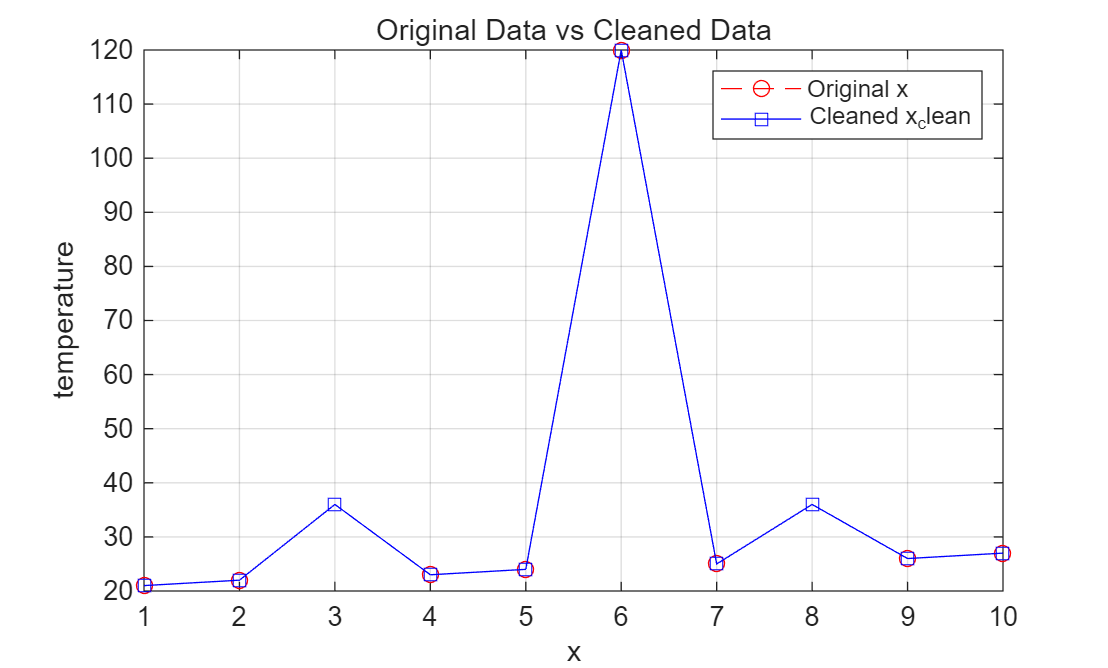


%b번 문제
idx_missing=isnan(x);

%c번 문제
mu0=mean(x,'omitnan');
sig0=std(x,'omitnan');

%d번 문제
idx_outlier=abs(x-mu0)>3*sig0;

%e번 문제
x_temp=x;
x_temp(idx_missing|idx_outlier)=NaN;

%f번 문제
meanTemp=mean(x_temp,'omitnan');
x_clean=x_temp;
x_clean(isnan(x_clean))=meanTemp;


%g번 문제
mu_clean=mean(x_clean);
sig_clean=std(x_clean);

%h번 문제
figure;
plot(x,'ro--');
hold on;
plot(x_clean,'bs-');
xlabel('x');
ylabel('temperature');
title('Original Data vs Cleaned Data');
legend('Original x','Cleaned x_clean');
grid on;

2번 문제

clear;
clc;

%a번 문제
A=[10 200 0.5;12 180 0.7;15 220 0.6;20 250 0.9;25 300 1.1];
disp(A);

   10.0000  200.0000    0.5000
   12.0000  180.0000    0.7000
   15.0000  220.0000    0.6000
   20.0000  250.0000    0.9000
   25.0000  300.0000    1.1000




%b번 문제
colMin=min(A);
colMax=max(A);

%c번 문제 
A_norm=(A-colMin)./(colMax-colMin);
disp(A_norm);

         0    0.1667         0
    0.1333         0    0.3333
    0.3333    0.3333    0.1667
    0.6667    0.5833    0.6667
    1.0000    1.0000    1.0000




%d번 문제
rowMean=mean(A_norm,2);

%e번 문제
[~,idx]=max(rowMean);

%f번 문제
bestOriginal=A(idx,:);
bestNormalized=A_norm(idx,:);

3번 문제

clear;
clc;

%a번 문제
Channel=["CH1";"CH2";"CH3";"CH4";"CH5";"CH6";"CH7";"CH8"];
Signal=[18.2;15.5;21.0;11.7;25.3;19.4;28.6;16.8];
Noise=[2.1;3.4;2.8;4.2;3.0;5.1;2.9;3.7];
T=table(Channel,Signal,Noise);
disp(T);

    Channel    Signal    Noise
    _______    ______    _____

     "CH1"      18.2      2.1 
     "CH2"      15.5      3.4 
     "CH3"        21      2.8 
     "CH4"      11.7      4.2 
     "CH5"      25.3        3 
     "CH6"      19.4      5.1 
     "CH7"      28.6      2.9 
     "CH8"      16.8      3.7 




%b번 문제
T.SignalToNoise=T.Signal./T.Noise;

%c번 문제
meanSNR=mean(T.SignalToNoise);

%d번 문제
T_high=T(T.SignalToNoise>meanSNR,:);

%e번 문제
snrVec=T_high{:,'SignalToNoise'};

%f번 문제
varSNR=var(snrVec);

4번 문제

clear;
clc;

%a번 문제
Wine = readtable('wine.data','FileType','text','Delimiter',',','ReadVariableNames',false);

%b번 문제
Wine.Properties.VariableNames={'Class','Alcohol','MalicAcid','Ash','Alcalinity','Magnesium','Phenols','Flavanoids','Nonflavanoid','Proanthocyanins', 'ColorIntensity', 'Hue', 'OD280', 'Proline'};

%c번 문제
X=Wine{:,{'Alcohol','MalicAcid','ColorIntensity'}};

%d번 문제
X_std=(X-mean(X,1))./std(X,0,1);

%e번 문제
normVec=sqrt(sum(X_std.^2,2));

%f번 문제
cutoff=prctile(normVec,90);

%g번 문제
T_top=Wine(normVec>=cutoff,:);

%h번 문제
disp(T_top(:, {'Class','Alcohol','MalicAcid','ColorIntensity'}));

    Class    Alcohol    MalicAcid    ColorIntensity
    _____    _______    _________    ______________

      2       11.41       0.74            3.08     
      2       11.03       1.51             1.9     
      2       13.05        5.8             2.6     
      3       12.53       5.51               5     
      3       13.62       4.95             4.4     
      3       13.88       5.04             4.9     
      3       12.79       2.67            10.8     
      3       13.23        3.3           10.52     
      3       13.17       5.19             7.9     
      3       13.84       4.12            9.01     
      3       14.34       1.68              13     
      3       13.48       1.67           11.75     
      3       13.45        3.7           10.68     
      3        13.4        4.6             8.5     
      3       14.16       2.51             9.7     
      3       13.71       5.65             7.7     
      3       13.27       4.28            10.2     
      3    

5번 문제

clear;
clc;

rng(1);
%a번 문제
y=50+5*randn(100,1);

%b번 문제
y(10)=90;
y(25)=95;
y(40)=5;
y(70)=100;
y(90)=0;

%c번 문제
Q1=quantile(y, 0.25);
Q3=quantile(y, 0.75);
disp(Q1);

   46.8183



disp(Q3);

   53.5856




%d번 문제
IQRval=Q3-Q1;
disp(IQRval);

    6.7673




%e번 문제
lower=Q1-1.5*IQRval;
upper=Q3+1.5*IQRval;
disp(lower);

   36.6673



disp(upper);

   63.7366




%f번 문제
idx_outlier=(y<lower)|(y>upper);

%g번 문제
y_clean=y(~idx_outlier);
med_clean=median(y_clean);

6번 문제

clear;
clc;

%a번 문제
Device={'D1';'D2';'D3';'D4';'D5';'D6';'D7';'D8';'D9';'D10';'D11';'D12'};
Power=[110;130;125;160;170;150;190;200;210;180;220;240];
Throughput=[42;50;48;61;65;57;72;75;79;69;83;91];
DeviceData=table(Device,Power,Throughput);

%b번 문제
power=DeviceData.Power;
throughput=DeviceData.Throughput;
disp(power);

   110
   130
   125
   160
   170
   150
   190
   200
   210
   180
   220
   240



disp(throughput);

    42
    50
    48
    61
    65
    57
    72
    75
    79
    69
    83
    91




%c번 문제
R=corrcoef(power,throughput);
rValue=R(1,2);

%d번 문제
if rValue>=0.7
    disp('Strong correlation');
else
    disp('Weak correlation');
end

Strong correlation


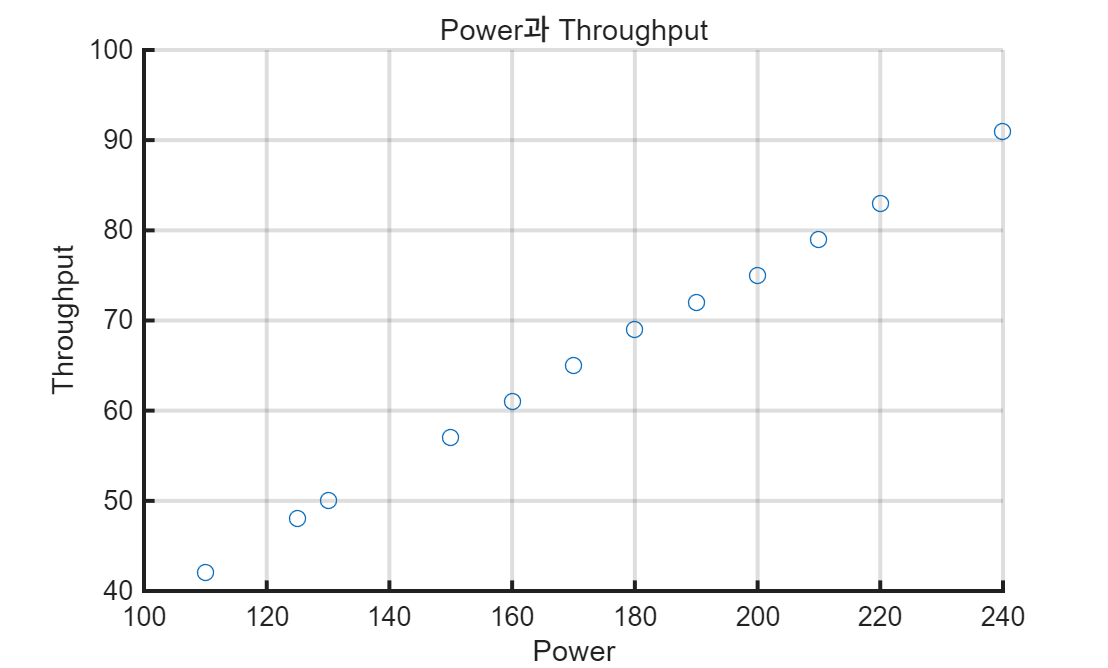


%e번 문제
figure;
scatter(power,throughput);

%f번 문제
xlabel('Power', 'FontSize', 10);
ylabel('Throughput', 'FontSize', 10);
title('Power과 Throughput', 'FontSize', 10);
set(gca,'FontSize',10,'LineWidth',1.5);
grid on;

7번 문제

clear;
clc;

%a번 문제
Material={'A';'A';'A';'A';'B';'B';'B';'B';'C';'C';'C';'C'};
EnergyDensity=[245;252;238;260;310;295;305;318;180;190;176;185];
Battery=table(Material,EnergyDensity);

%b번 문제
Aidx=strcmp(Battery.Material,'A');
Bidx=strcmp(Battery.Material,'B');
Cidx=strcmp(Battery.Material,'C');

%c번 문제
meanA=mean(Battery.EnergyDensity(Aidx));
meanB=mean(Battery.EnergyDensity(Bidx));
meanC=mean(Battery.EnergyDensity(Cidx));

%d번 문제
stdA=std(Battery.EnergyDensity(Aidx));
stdB=std(Battery.EnergyDensity(Bidx));
stdC=std(Battery.EnergyDensity(Cidx));

%e번 문제
Summary=table({'A';'B';'C'},[meanA; meanB; meanC],[stdA; stdB; stdC],'VariableNames',{'Material','Mean','Std'});

%f번 문제
G=groupsummary(Battery, 'Material', {'mean','std'}, 'EnergyDensity');

8번 문제

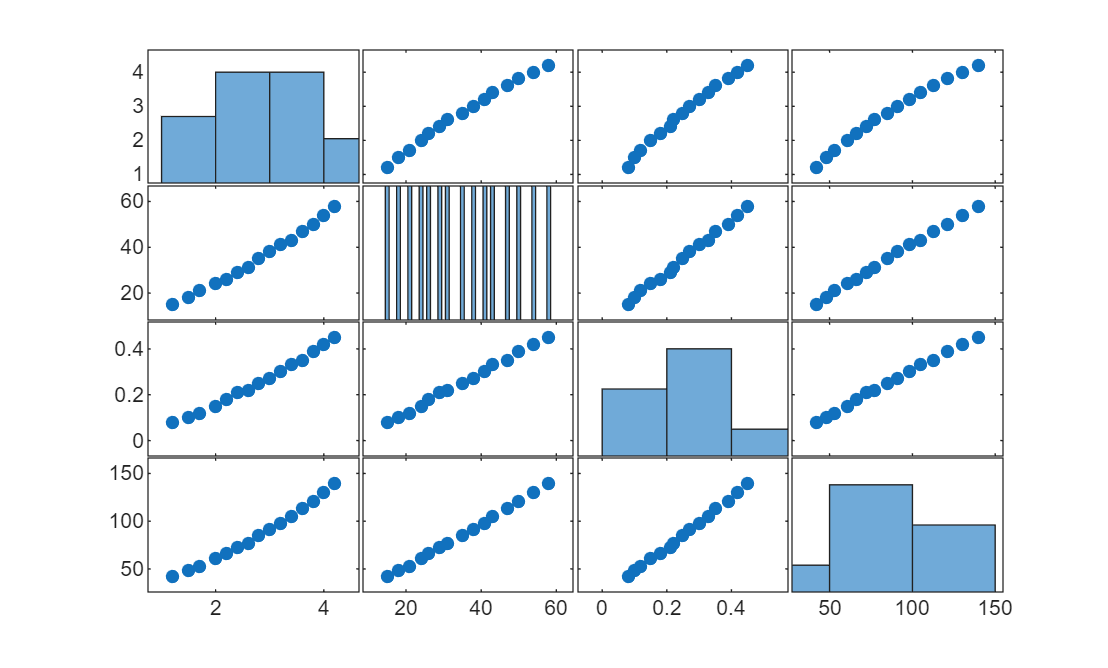

clear;
clc;

%a번 문제
Speed=[1.2;1.5;1.7;2.0;2.2;2.4;2.6;2.8;3.0;3.2;3.4;3.6;3.8;4.0;4.2];
Torque=[15;18;21;24;26;29;31;35;38;41;43;47;50;54;58];
SlipRate=[0.08;0.10;0.12;0.15;0.18;0.21;0.22;0.25;0.27;0.30;0.33;0.35;0.39;0.42;0.45];
EnergyUse=[42;48;53;61;66;72;77;85;91;98;105;113;121;130;140];
Robot=table(Speed, Torque, SlipRate, EnergyUse);

%b번 문제
X=table2array(Robot);

%c번 문제
figure;
plotmatrix(X);


%d번 문제
varVec=var(X);

%e번 문제
[~,idxMax] = max(varVec);

%f번 문제
maxVarName=Robot.Properties.VariableNames{idxMax};
disp(maxVarName);

EnergyUse


9번 문제

clear;
clc;

%a번 문제
T=readtable('train.csv');

%b번 문제
numMissingAge=sum(ismissing(T.Age));

%c번 문제
meanAge=mean(T.Age,'omitnan');
T.Age=fillmissing(T.Age,'constant',meanAge);

%d번 문제
muFare = mean(T.Fare);
sigFare = std(T.Fare);

%e번 문제
lower=muFare-3*sigFare;
upper=muFare+3*sigFare;
idx=(T.Fare>=lower)&(T.Fare<=upper);
T_clean=T(idx,:);

%f번 문제
meanAge0=mean(T_clean.Age(T_clean.Survived == 0));

%g번 문제
meanAge1=mean(T_clean.Age(T_clean.Survived == 1));

%h번 문제
Result=table([0;1],[meanAge0; meanAge1],'VariableNames', {'Survived','MeanAge'});
disp(Result);

    Survived    MeanAge
    ________    _______

       0        30.395 
       1        28.467 



10번 문제

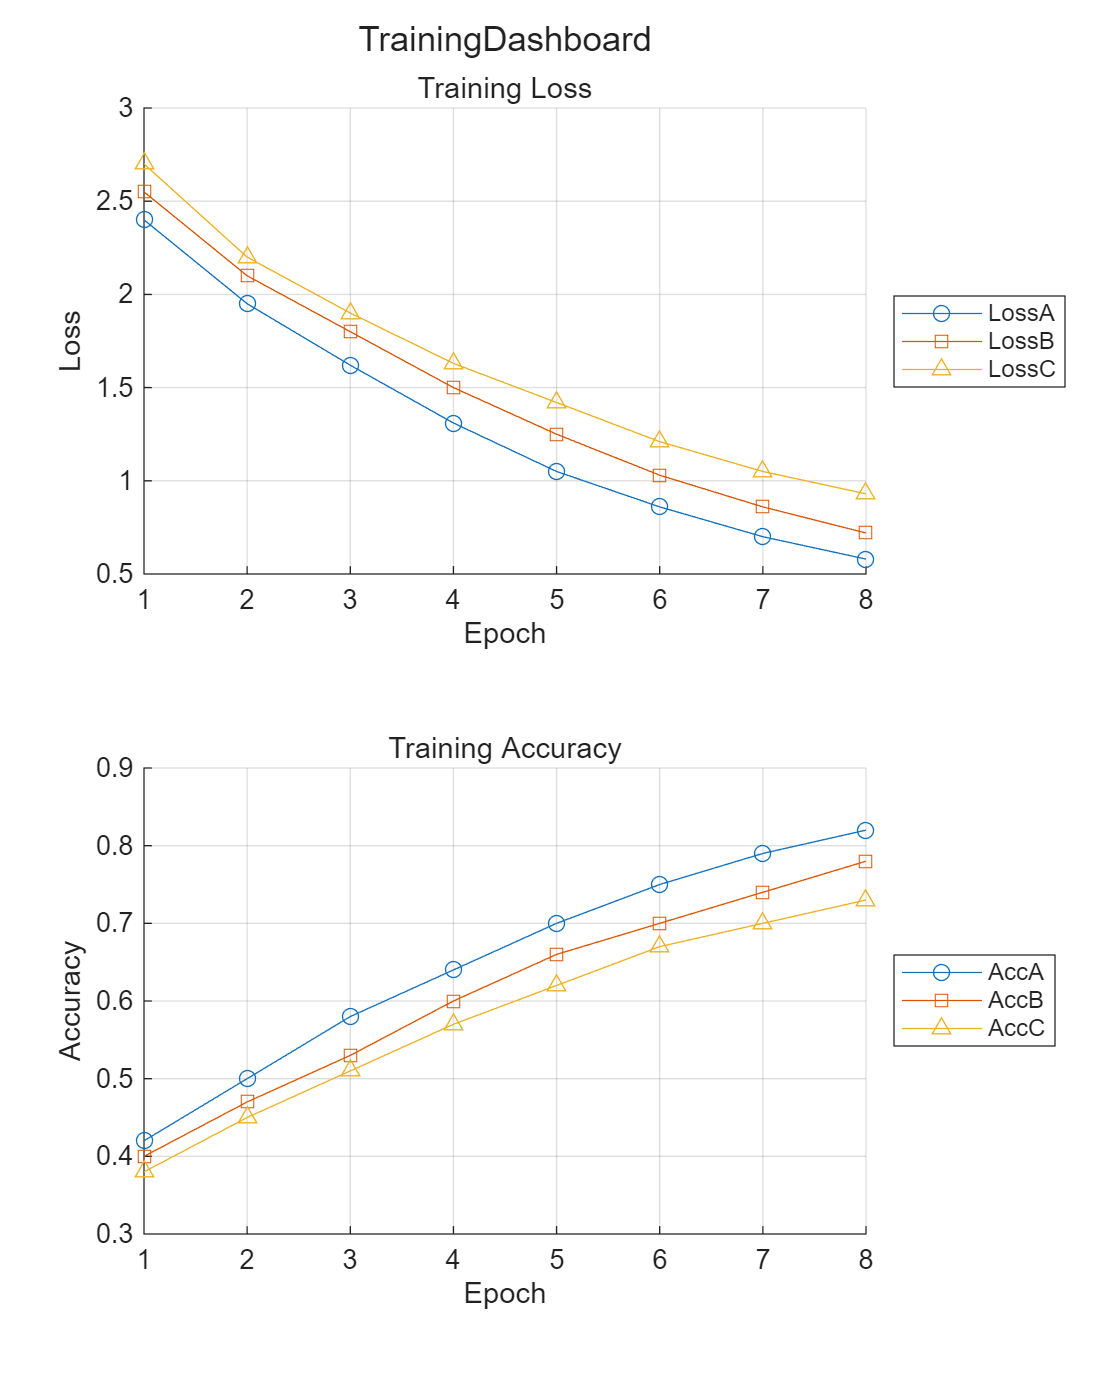

clear;
clc;

%a번 문제
Epoch=[1;2;3;4;5;6;7;8];
LossA=[2.40;1.95;1.62;1.31;1.05;0.86;0.70;0.58];
LossB=[2.55;2.10;1.80;1.50;1.25;1.03;0.86;0.72];
LossC=[2.70;2.20;1.90;1.63;1.42;1.21;1.05;0.93];
AccA=[0.42;0.50;0.58;0.64;0.70;0.75;0.79;0.82];
AccB=[0.40;0.47;0.53;0.60;0.66;0.70;0.74;0.78];
AccC=[0.38;0.45;0.51;0.57;0.62;0.67;0.70;0.73];
TrainLog = table(Epoch, LossA, LossB, LossC, AccA, AccB, AccC);
figure('Position',[100 300 800 1000]);


%b번 문제
t=tiledlayout(2,1);

%c번 문제
nexttile;
hold on;
plot(Epoch,LossA,'-o');
plot(Epoch,LossB,'-s');
plot(Epoch,LossC,'-^');
hold off;

%e번 문제 
legend('LossA','LossB','LossC','Location','eastoutside');
xlabel('Epoch');
ylabel('Loss');
title('Training Loss');
grid on;


%d번 문제
nexttile;
hold on;
plot(Epoch,AccA,'-o');
plot(Epoch,AccB,'-s');
plot(Epoch,AccC,'-^');
hold off;

%e번 문제
legend('AccA','AccB','AccC','Location','eastoutside');
xlabel('Epoch');
ylabel('Accuracy');
title('Training Accuracy');
grid on;

%f번 문제
title(t,'TrainingDashboard');

11번 문제

clear;
clc;

%a번 문제
A=[3 -1 5 -2 4;-4 6 -3 2 1;7 -5 8 -1 0;-2 4 -6 9 3;5 -3 2 -4 6];

%b번 문제
A_clean=A;

%c번 문제
for i=1:size(A_clean,1)
    for j=1:size(A_clean,2)
        %d번 문제
        if A_clean(i,j)<0
            A_clean(i,j)=0;
        end
    end
end

%e번 문제
disp(A);

     3    -1     5    -2     4
    -4     6    -3     2     1
     7    -5     8    -1     0
    -2     4    -6     9     3
     5    -3     2    -4     6



disp(A_clean);

     3     0     5     0     4
     0     6     0     2     1
     7     0     8     0     0
     0     4     0     9     3
     5     0     2     0     6



12번 문제

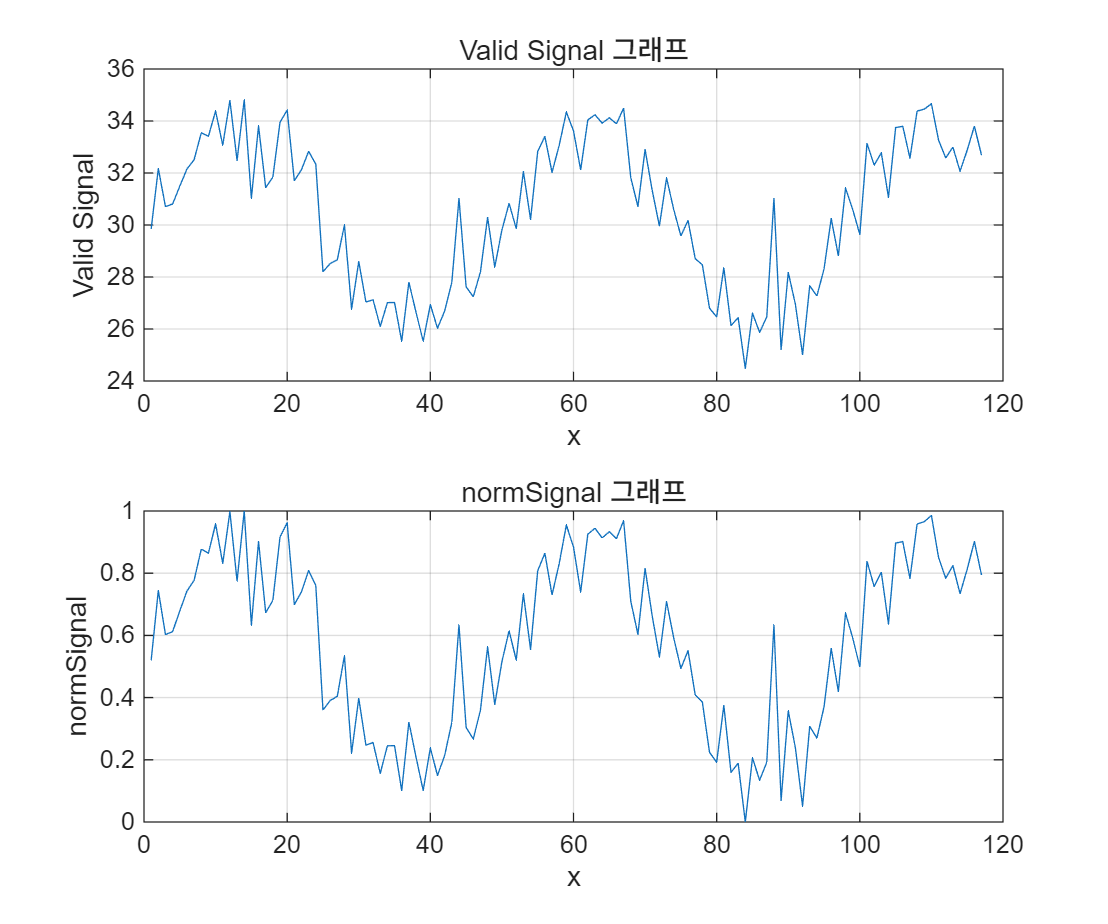

clear;
clc;

%a번 문제
rng(1);

%b번 문제
t=(1:120)';

%c번 문제
signal=30+4*sin(t/8)+randn(120,1);

%d번 문제
signal(15)=NaN;
signal(45)=NaN;
signal(90)=NaN;

%e번 문제
signal(30)=80;
signal(75)=-20;
signal(110)=95;

%f번 문제
idxMissing=isnan(signal);
numMissing=sum(idxMissing);

%g번 문제
meanSignal=mean(signal,'omitnan');
signalFilled=signal;
signalFilled(idxMissing)=meanSignal;

%h번 문제
mu=mean(signalFilled);
sig=std(signalFilled);
idxOutlier=abs(signalFilled-mu)>3*sig;

%i번 문제
signalClean=signalFilled;
signalClean(idxOutlier)=NaN;

%j번 문제
validSignal=signalClean(~isnan(signalClean));

%k번 문제
normSignal=(validSignal-min(validSignal))/(max(validSignal)-min(validSignal));

%l번 문제
finalMean=mean(normSignal);
finalVar=var(normSignal);

%m번 문제
figure('Position',[1000 1000 1200 1000]);
tiledlayout(2,1);
nexttile;
plot(validSignal);
xlabel('x');
ylabel('Valid Signal');
title('Valid Signal 그래프');
grid on;

nexttile;
plot(normSignal);
xlabel('x');
ylabel('normSignal');
title('normSignal 그래프');
grid on;

13번 문제

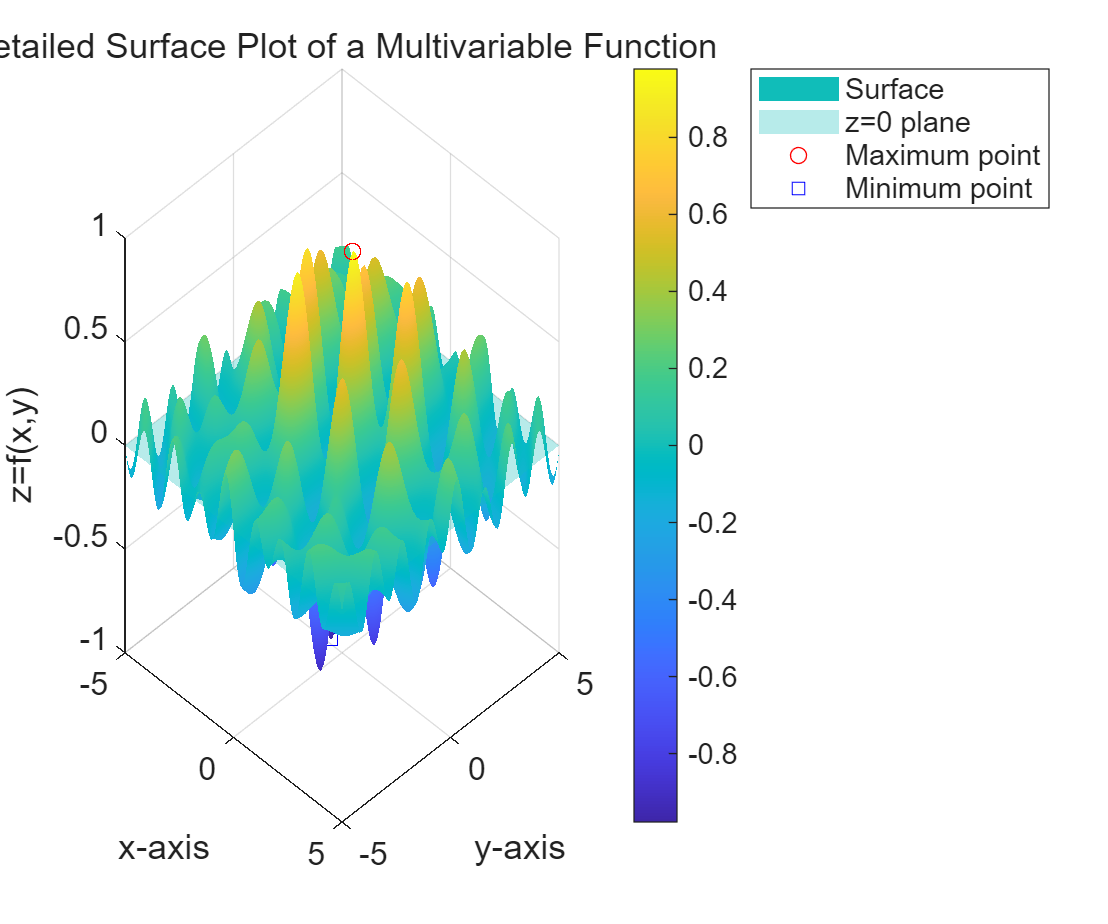

clear;
clc;

%a번 문제
x=-5:0.05:5;
y=-5:0.05:5;
[X,Y]=meshgrid(x,y);

%b번 문제
Z=exp(-0.08*(X.^2+Y.^2)).*sin(3*X).*cos(2*Y)+0.15*sin(X.*Y);

%c번 문제
figure('Position',[100 100 1200 1000]);
surf(X,Y,Z);
hold on;

%d번 문제
shading interp;
colorbar;

%e번 문제
xlabel('x-axis');
ylabel('y-axis');
zlabel('z=f(x,y)');

%f번 문제
title('Detailed Surface Plot of a Multivariable Function');

%g번 문제
grid on;
set(gca,'FontSize',12);

%h번 문제
view(45,30);

%i번 문제
planeZ=zeros(size(Z));
surf(X,Y,planeZ,'FaceAlpha',0.3,'EdgeColor','none');

%j번 문제
maxZ=max(Z(:));
minZ=min(Z(:));

%k번 문제
[rowMax,colMax]=find(Z==maxZ,1);
[rowMin,colMin]=find(Z==minZ,1);
maxPoint=[X(rowMax,colMax),Y(rowMax,colMax),maxZ];
minPoint=[X(rowMin,colMin),Y(rowMin,colMin),minZ];

%l번 문제
plot3(maxPoint(1),maxPoint(2),maxPoint(3),'ro');
plot3(minPoint(1),minPoint(2),minPoint(3),'bs');
legend('Surface','z=0 plane','Maximum point','Minimum point');

%m번 문제
saveas(gcf,'complex_surface.png');